clear;

WAV = "H:\Code\rust\mwsave\LICENSEr.wav";

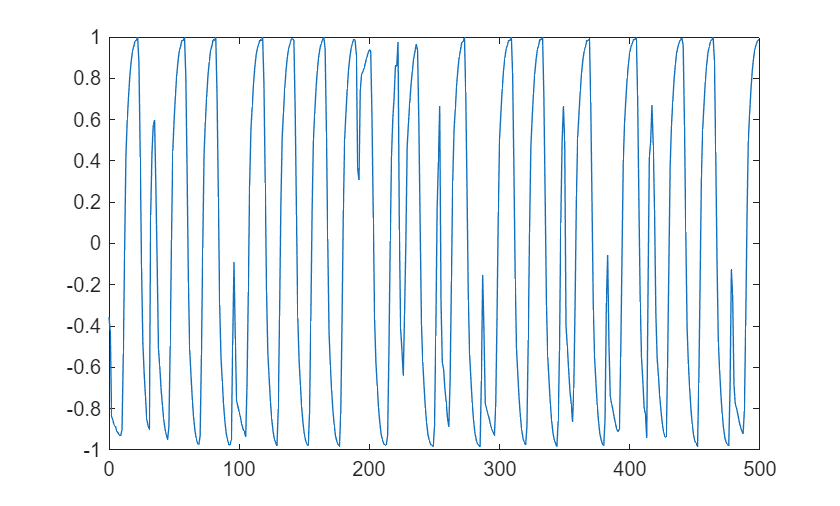

[y, rFs] = audioread(WAV);
y = y(:, 1);
y_max = max(y);
qf = 1 / y_max;
y = y * qf;
y = awgn(y, 100, 'measured');
plot(0:499, y(139341:139840, 1));

P = 32;

Fs = 48000;
f = 2000;
A = 1;

sync_1t = 0:1/Fs:127/Fs;
sync_1w = A * sin(2 * pi * 1000 * sync_1t).';
sync_2t = 0:1/Fs:127/Fs;
sync_2w = A * sin(2 * pi * 3000 * sync_2t).';
sync_s = [sync_1w; sync_2w; sync_1w; sync_2w];
start_i = 0;
for i = 128 * 4 + 1:length(y)
    t = y(i - (128 * 4) : i - 1, 1);
    r = t .* sync_s;
    v = sum(r);
    if v >= 200
        start_i = i;
        break;
    end
end
y = y(start_i:end, 1);
t = 0:1/Fs:(length(y) - 1)/Fs;
std_w = A * sin(2 * pi * f * t);
std_w = std_w.';

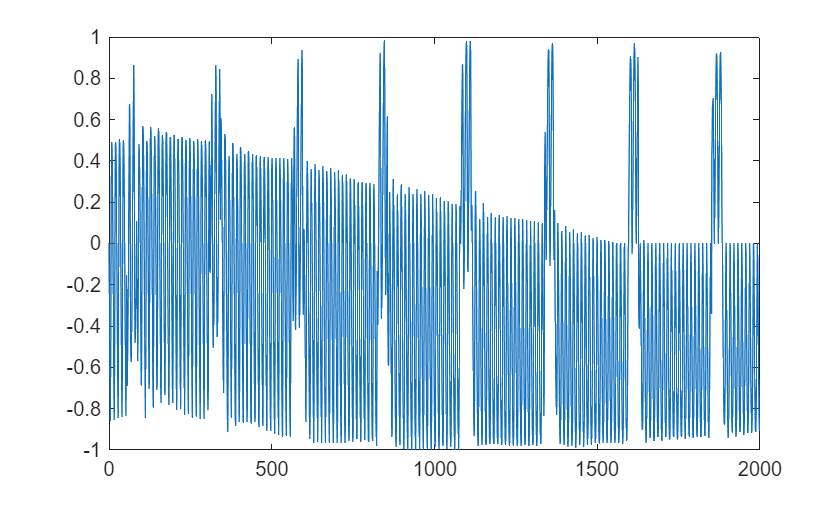

soft_info = y(:, 1) .* std_w;
window_length = 1;
window = zeros(window_length, 1);
filted_soft_info = zeros(size(soft_info));
data_length = length(soft_info);
soft_info = [soft_info; window];
for i = 1:data_length
    window = soft_info(i:i - 1 + window_length, 1);
    filted_soft_info(i, 1) = mean(window);
end
soft_info = filted_soft_info;
plot(0:1999, soft_info(12901:14900, 1));

target_wav_length = ceil(length(soft_info) / P) * P;
ext_length = target_wav_length - length(soft_info);
soft_info = [soft_info; zeros(ext_length, 1)];
soft_data_in_part = reshape(soft_info, P, []);
soft_bits = mean(soft_data_in_part);
hard_bits = zeros(size(soft_bits));
hard_bits(soft_bits >= 0) = 1;
hard_bits(soft_bits < 0) = 0;
target_length = ceil(length(hard_bits) / 8) * 8;
ext_length = target_length - length(hard_bits);
hard_bits = [hard_bits, zeros(1, ext_length)];
hard_bits = reshape(hard_bits.', 8, []);
file_in_byte = size(hard_bits, 2);
file_byte = zeros(1, file_in_byte);
for i = 1:8
    file_byte(1, :) = hard_bits(i, :) * (2 ^ (i - 1)) + file_byte(1, :);
end

si = 0;
ei = 0;
for i = 1:length(file_byte)
    s = char(file_byte(1, i:i + 9));
    e = char(file_byte(1, i:i + 14));
    if s == "File info:"
        si = i;
    end
    if e == ".End file info."
        ei = i;
    end

    if si ~= 0 && ei ~= 0
        break;
    end
end

位置 2 处的索引超出数组边界。索引不能超过 36109。

file_info = char(file_byte(1, si + 10:ei - 1));
info_p = split(file_info, ',');
file_name = info_p{1, 1};
file_size = str2double(info_p{2, 1});
% file_hash = info_p{3, 1};

file_body = file_byte(1, ei + 15:ei + 14 + file_size).';
% fh = DataHash(uint8(file_body));
% if fh == file_hash
%     disp(strcat("Get ", file_name, " success!"));
% else
%     disp(strcat("Get ", file_name, " failed!"));
% end

FILE = strcat("H:\", file_name);
lf = fopen(FILE, "w");
fwrite(lf, file_body);
fclose(lf);